% HW 6, problem 2
%
% The idft function we worked on lab 6
% defines the matrix WiDFT = Wnc .^ (n' * n);
% Wnc = exp(j*2*pi/N); and n = 0:1:N-1;
% We computed x(n) = Xk * WiDFT / N
% since we have x(n), we compute
% Xk = N * x(n) * Inverse(WiDFT)
N = 4;
n = 0:1:N-1;
Wnc = exp(j*2*pi/N);
WiDFT = Wnc .^ (n' * n);

xn = [1 2 3 1];
Xk = N * xn * (WiDFT ^ -1);
Xk' % to show all the values of Xk

ans =    7.0000 + 0.0000i
  -2.0000 + 1.0000i
   1.0000 - 0.0000i
  -2.0000 - 1.0000i


Xk2 = dft(xn,4);
Xk2'

ans =    7.0000 + 0.0000i
  -2.0000 + 1.0000i
   1.0000 - 0.0000i
  -2.0000 - 1.0000i



sum(abs(Xk - Xk2)) % to show it's 0, or almost 0 (precision errors)

ans = 4.0842e-15

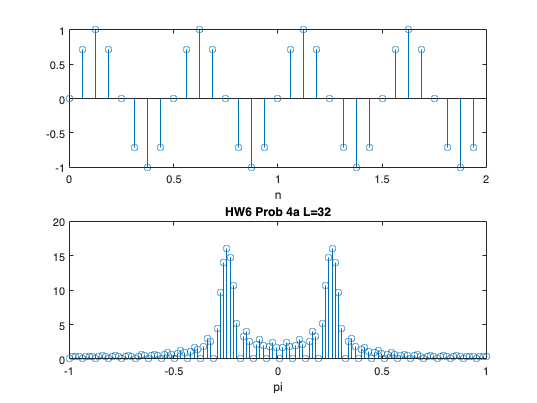

% HW 6 - Problem 4
figure;
L = 32;
Fs = 16;
Ts = 1/Fs;
t = 0:Ts:(L-1)*Ts;
FN = 128;
w = -1:2/(FN-1):1;


f = sin(4*pi*t);
Fk = fftshift(fft(f,FN));
figure;
subplot(2,1,1);
stem(t, f);
xlabel('n')
subplot(2,1,2);
stem(w,abs(Fk));
xlabel('pi');
title('HW6 Prob 4a L=32');

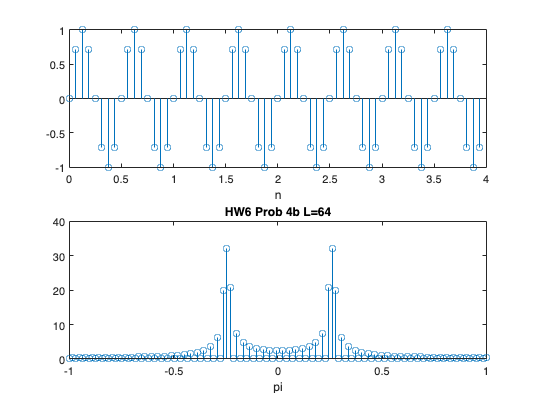


L = 64;
t = 0:Ts:(L-1)*Ts;
f = sin(4*pi*t);
Fk = fftshift(fft(f,FN));
figure;
subplot(2,1,1);
stem(t, f);
xlabel('n')
subplot(2,1,2);
stem(w,abs(Fk));
xlabel('pi');
title('HW6 Prob 4b L=64');

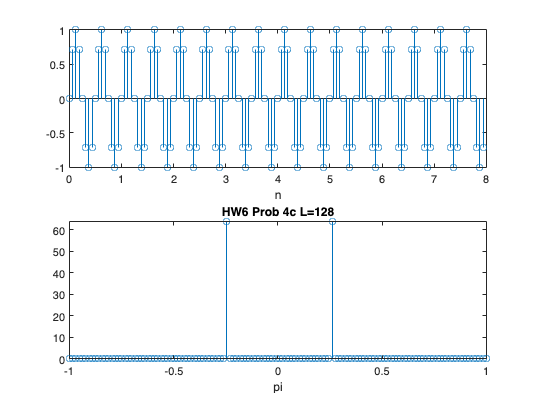


L = 128;
t = 0:Ts:(L-1)*Ts;
f = sin(4*pi*t);
Fk = fftshift(fft(f,FN));
figure;
subplot(2,1,1);
stem(t, f)
xlabel('n')
subplot(2,1,2);
stem(w,abs(Fk));
xlabel('pi');
title('HW6 Prob 4c L=128');


% The increase in the number of samples L increases the
% frequency resolution. Because the increase in samples
% also changes the length of the window function
% multiplying the signal, it reduces the leakage so
% the sinusoidal signal is more focused (like an impulse)


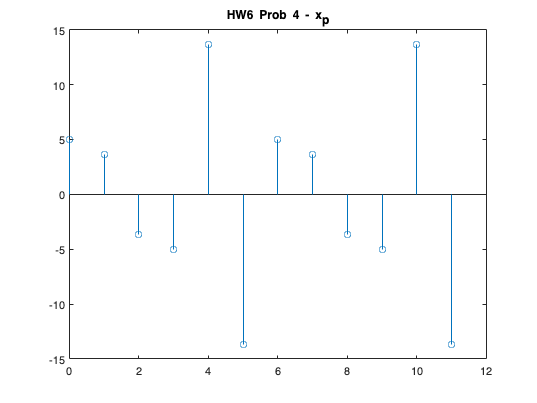

% HW 6 - problem 3
% a) First cosine term has frequency of 1/2 while
% the sin has frequency 1/3. N is such that
% 2*pi*N/2 = 2*pi*k and 2*pi*N/3 = 2*pi*l
% So from first term N = 2k, i.e., a multiple of 2
% from second term, N = 3l, i.e., a multiple of 3
% thus N = 6
clf;
N = 6;
n = 0:(2*N -1);
x2 = 5*cos(pi*n) + 10*sin(2*pi*n/3);
x1 = x2(1:1:N);
stem(n, x2);
title('HW6 Prob 4 - x_p');

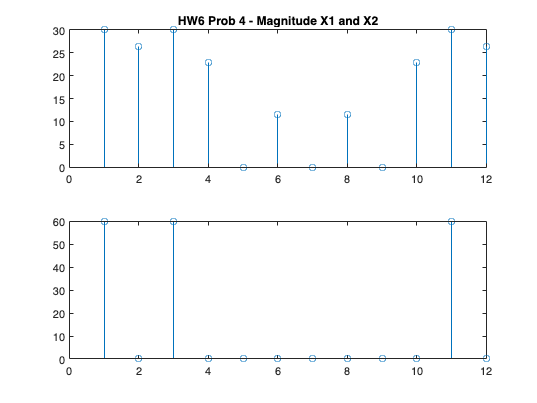


X1 = fftshift(fft(x1, 2*N));
X2 = fftshift(fft(x2, 2*N));
figure;
subplot(2,1,1);
stem(abs(X1));
title('HW6 Prob 4 - Magnitude X1 and X2');
subplot(2,1,2);
stem(abs(X2));

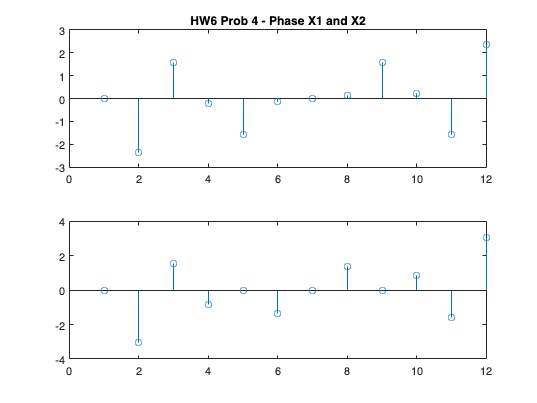


figure;
subplot(2,1,1);
stem(angle(X1));
title('HW6 Prob 4 - Phase X1 and X2');
subplot(2,1,2);
stem(angle(X2));